clear all
clc
img = imread(['..\DB0/db0_4.jpg']);
%imshow(generateFaceMask(colorCorrection(im2double(img))).*im2double(img
% fm =  generateFaceMask(colorCorrection(im2double(img)));
% mm = mouthMask(colorCorrection(im2double(img)),fm)
% imshow(mm.*im2double(img))
findEyeCoordinates(im2double(img))

ans =   184.7073  263.3836
  299.4488  261.3230


i = 1

rotation = 2

toneValue = 0.9400

result = 1

dist = 193.4684

ans = 'Pass'

ans = '========='

i = 2

rotation = -1

toneValue = 1.3000

result = 2

dist = 443.8392

ans = 'Pass'

ans = '========='

i = 3

rotation = -5

toneValue = 1.2300

result = 3

dist = 162.2977

ans = 'Pass'

ans = '========='

i = 4

rotation = 5

toneValue = 1.1800

result = 4

dist = 444.1625

ans = 'Pass'

ans = '========='

i = 5

rotation = -4

toneValue = 0.8500

result = 5

dist = 79.3995

ans = 'Pass'

ans = '========='

i = 6

rotation = -2

toneValue = 1.1100

result = 6

dist = 665.0949

ans = 'Pass'

ans = '========='

i = 7

rotation = -4

toneValue = 1.1300

result = 7

dist = 683.2264

ans = 'Pass'

ans = '========='

i = 8

rotation = -4

toneValue = 1.0900

result = 8

dist = 448.6522

ans = 'Pass'

ans = '========='

i = 9

rotation = 0

toneValue = 1.1700

result = 9

dist = 996.4974

ans = 'Pass'

ans = '========='

i = 10

rotation = 2

toneValue = 1.2500

result = 0

dist = 1.0697e+03

ans = 'Fail'

ans = '========='

i = 11

rotation = 4

toneValue = 0.9000

result = 0

dist = 99999999

ans = 'Fail'

ans = '========='

i = 12

rotation = 2

toneValue = 0.8200

result = 12

dist = 642.8621

ans = 'Pass'

ans = '========='

i = 13

rotation = -5

toneValue = 1.1500

result = 0

dist = 1.0739e+03

ans = 'Fail'

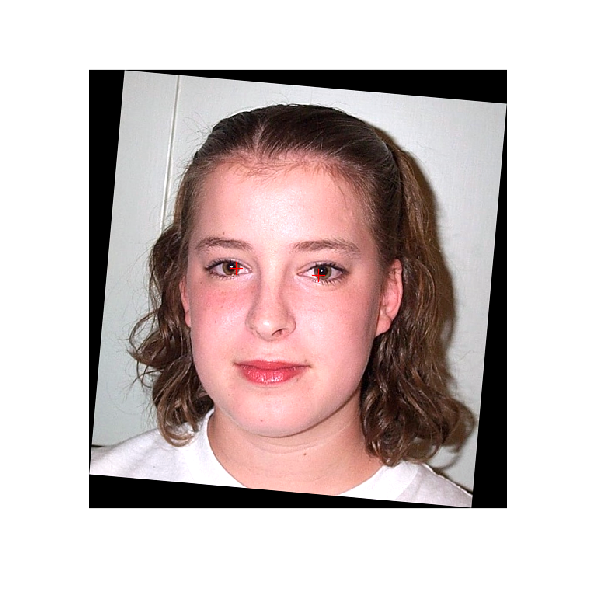

ans = '========='

i = 14

rotation = 0

toneValue = 0.9900

result = 14

dist = 17.8796

ans = 'Pass'

ans = '========='

i = 15

rotation = 4

toneValue = 1.0700

result = 15

dist = 349.6484

ans = 'Pass'

ans = '========='

i = 16

rotation = 1

toneValue = 1.2200

result = 16

dist = 229.2012

ans = 'Pass'

ans = '========='



%6 11
% img = im2double(img);
% img = colorCorrection(img);
% eyeCoords = findEyeCoordinates(img);
% if eyeCoords ~= 0
%     eyeL = eyeCoords(1, :);
%     eyeR = eyeCoords(2, :);
%     imgD = im2double(img);
%     normalface = normalizeFace(eyeL, eyeR, imgD);
% end
% 
% imshow(img)
% 
% hold on
% plot(eyeCoords(1,1),eyeCoords(1,2), 'r+', 'MarkerSize', 10, 'LineWidth', 1);
% plot(eyeCoords(2,1),eyeCoords(2,2), 'r+', 'MarkerSize', 10, 'LineWidth', 1);
% hold off

% temp = 'C:\Users\jakob\Documents\GitHub\DB0\db0_4.jpg'
% r = 5
% 
% img = imread(temp);
% 
% %img = imrotate(img,r,'bicubic');
% 
% %eyeCoords = findEyeCoordinates(img);
% %cc = colorCorrection(img);
% 
% % img = im2double(img)
% % img = colorCorrection(img);
% % fm = generateFaceMask(img);
% % imshow(img)
% %imshowpair(img, cc, 'montage')
% 
%%%%result=createEigenDB('..\DB1/', img)
totCorrect = 0;
temp = '';
avg = 0;


failCounter = 0;

for i = 1:16
    if i < 10
        temp = strcat('..\DB1/db1_0',int2str(i));
        temp = strcat(temp,'.jpg');
    else
        temp = strcat('..\DB1/db1_',int2str(i));
        temp = strcat(temp,'.jpg');
    end
    i
    
    rotation = randi([-5,5])
    toneValue = randi([70,130])/100
    
    img = imread(temp);
    
    img = imrotate(img,rotation,'bicubic');
    img = img*toneValue;
    
    img = im2double(img);
    img = colorCorrection(img);
    
    eyeCoords = findEyeCoordinates(img);
    if eyeCoords ~= 0
        eyeL = eyeCoords(1, :);
        eyeR = eyeCoords(2, :);

        normalface = normalizeFace(eyeL, eyeR, img);
    end

    
    [result,dist]=createEigenDB('..\DB1/', img);
    result
    dist
    if i == result
        totCorrect = totCorrect +1;
        'Pass'
    else
        'Fail'
        if eyeCoords ~= 0
           failCounter = failCounter+1;
           imshow(img);
               hold on
               plot(eyeCoords(1,1),eyeCoords(1,2), 'r+', 'MarkerSize', 10, 'LineWidth', 1);
               plot(eyeCoords(2,1),eyeCoords(2,2), 'r+', 'MarkerSize', 10, 'LineWidth', 1);
               hold off
        end
        
    end
    '========='
end


%     hold on
%     plot(eyeCoords(1,1),eyeCoords(1,2), 'r+', 'MarkerSize', 10, 'LineWidth', 1);
%     plot(eyeCoords(2,1),eyeCoords(2,2), 'r+', 'MarkerSize', 10, 'LineWidth', 1);
%     hold off

for i = 1:4
    temp = strcat('..\DB0/db0_',int2str(i));
    temp = strcat(temp,'.jpg');

    i
    img = imread(temp);
    img = im2double(img);
    img = colorCorrection(img);
    [result,dist] = createEigenDB('..\DB1/', img);
    dist
    if 0 == result || 99 == result
        totCorrect = totCorrect +1;
        'Pass'
    else
        'Fail'
    end
    '========='
end

i = 1

dist = 1.1094e+03

ans = 'Pass'

ans = '========='

i = 2

dist = 1.8410e+03

ans = 'Pass'

ans = '========='

i = 3

dist = 1.7341e+03

ans = 'Pass'

ans = '========='

i = 4

dist = 99999999

ans = 'Pass'

ans = '========='

'Stats'

ans = 'Stats'

totCorrect

totCorrect = 17

procentCorrect = 100*totCorrect/20

procentCorrect = 85

avg/20

ans = 0